# Lysosome Stats

Use this script to generate the figures presented in the manuscript. 

Update Lysosome Methods discussion. 

Send Courtney names of large lysosomes

Send courtney stats of cell volumes

## Load Variables

Change directory to the Lysosome Analysis Folder 

clearvars -except paths proj
close all
clc
[VL, idT, cellT, dyingT,lysT] = loadProjectTables(paths);
idT = sortrows(idT,["Type", "Health"])

idT = 35×8 table
               Cell                Type             Lysosome               Health      TasteBud      Source      Dataset        Folder     
    ___________________________    ____    ___________________________    _________    ________    __________    _______    _______________

    "TB1_AP16_EM"                  "I"     "TB1_AP16__LYS_RSL"            "healthy"     "TB1"      "Rob"         "TF21"     "ROB_TF21_TB1" 
    "TB1_AP34_EM"                  "I"     "TB1_AP34_lys_RSL"             "healthy"     "TB1"      "Rob"         "TF21"     "ROB_TF21_TB1" 
    "TB1_AP36_EM"                  "I"     "TB1_AP36_LYS_RSL"             "healthy"     "TB1"      "Rob"         "TF21"     "ROB_TF21_TB1" 
    "TB1_A

### Examine Lysosome Volume Distributions

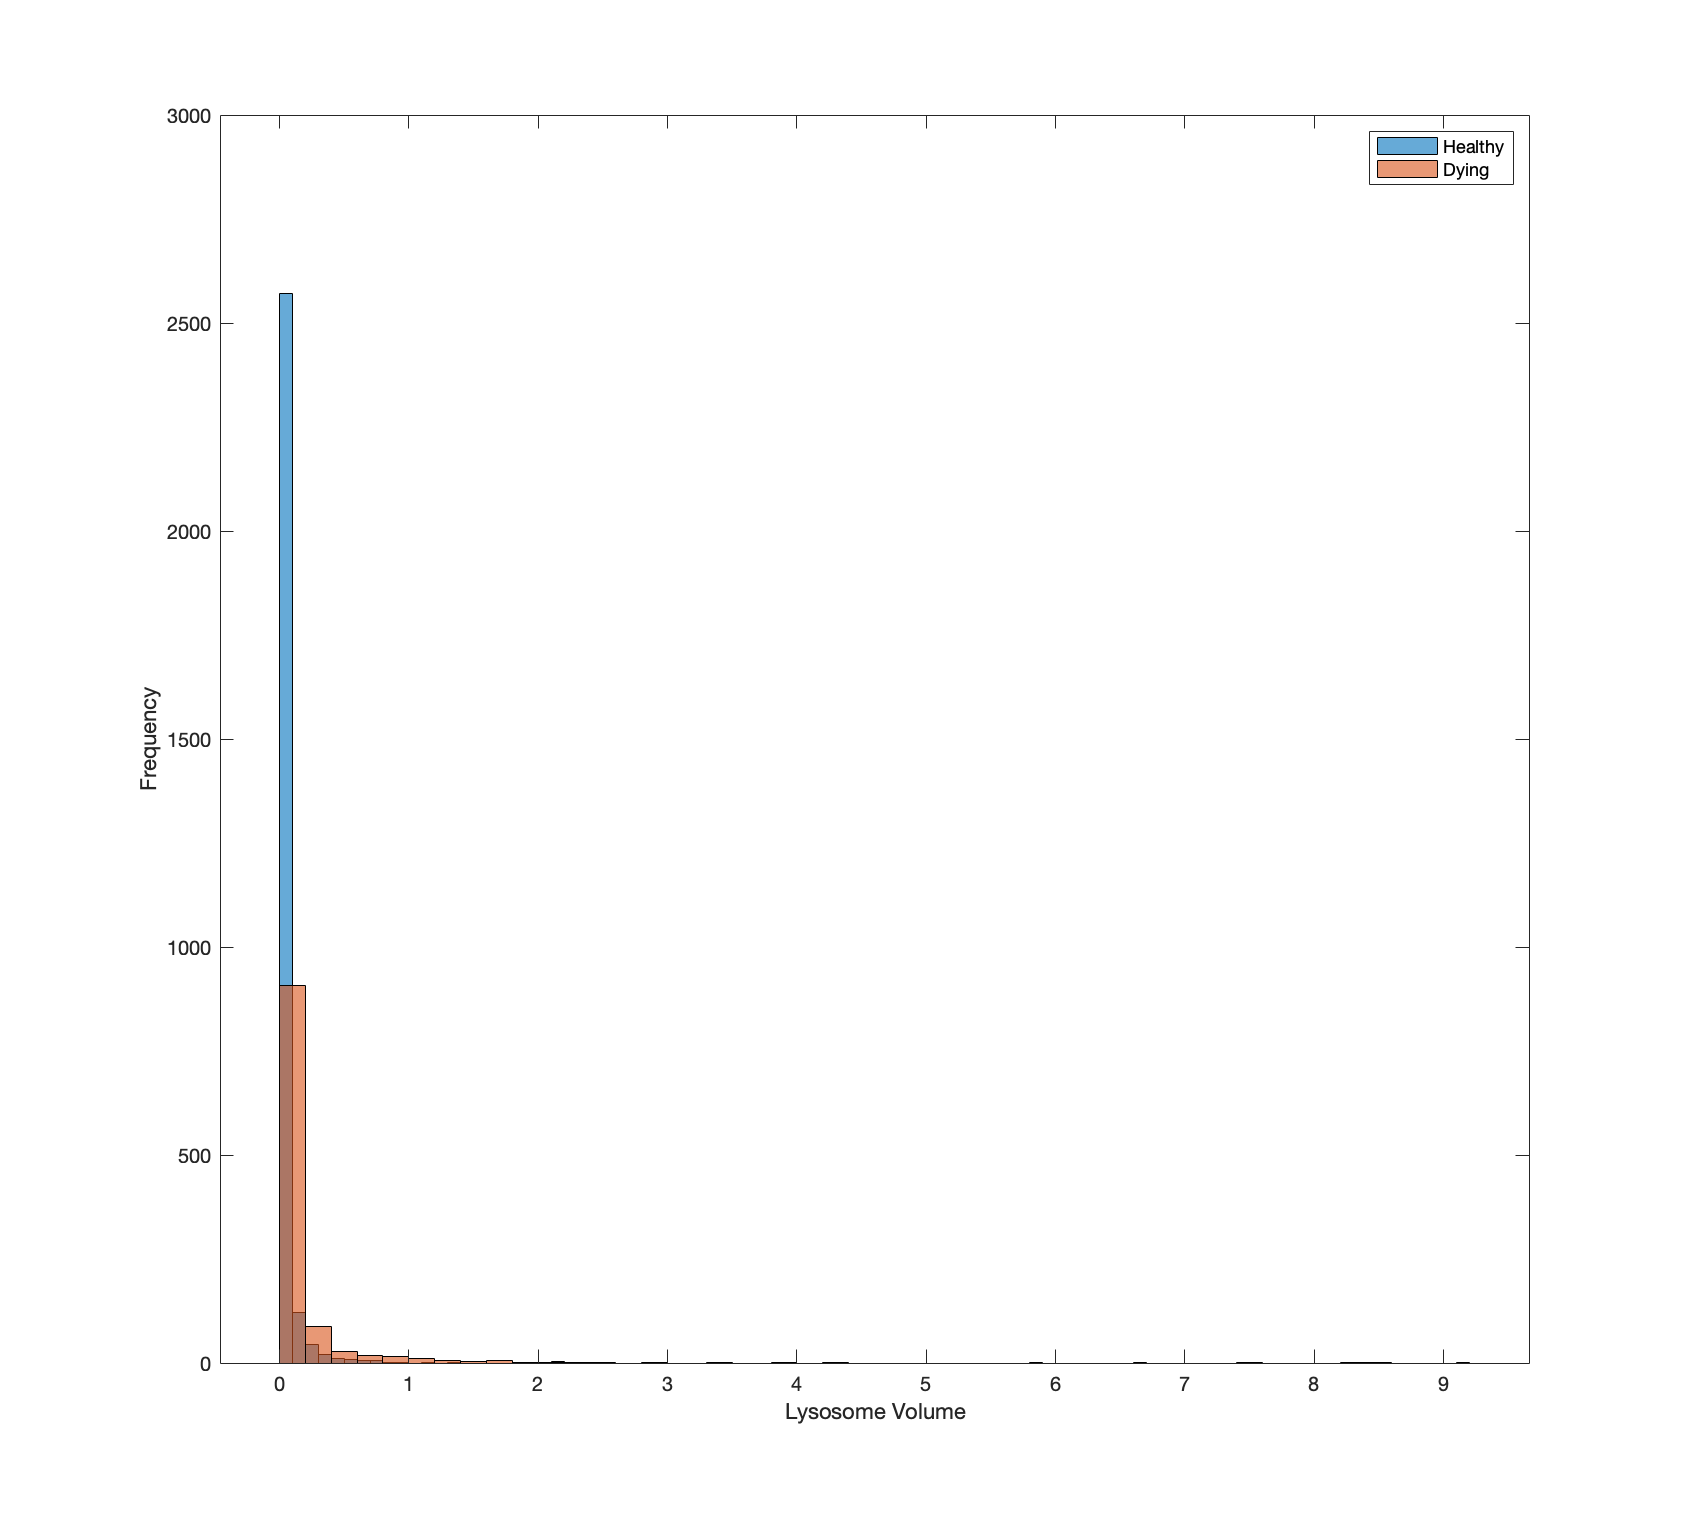

mmfig; 
la = lysT.Health =="healthy";
histogram(lysT.Volume(la))

hold on
histogram(lysT.Volume(~la))
ylabel('Frequency')
xlabel('Lysosome Volume')
legend('Healthy','Dying')

- volumes appear highly skewed

#### Examine Mean and Medians

groupsummary(lysT,"Health",["mean","median","range"],"Volume")

ans = 3×4 table
    Health     GroupCount    median_Volume    range_Volume
    _______    __________    _____________    ____________

    early          817          0.029769         8.4523   
    healthy       2810          0.008913         9.1295   
    late           277         0.0033482         1.7728   


- large differences between Mean and Median values further confirm non-normality

gs = groupsummary(lysT,"Health",{@skewness, @kurtosis},"Volume");
gs.Properties.VariableNames(3:4) = {'Skewness','Kurtosis'}

gs = 3×4 table
    Health     GroupCount    Skewness    Kurtosis
    _______    __________    ________    ________

    early          817        8.6592      100.58 
    healthy       2810        16.657       320.2 
    late           277        9.3039      112.72 


- volumes are highly skewed 

#### One-sample Kolmogorov-Smirnov test for normality of lysosomal volumes in each cell

h=1 means not normal

warning off
for n=unique(lysT.Cell)'

    x = lysT.Volume(lysT.Cell==n);
    if numel(x)>3
        [h, p] = kstest(x);     
        fprintf('%s: h = %d, p=%1.2f\n',n,h,p)       
    end
end
warning on

even per cell, volumes are not normal

### Largest Lysosome Volumes

[m,idc] = maxk(lysT.Volume,10)
lysT.Object(idc)

### Lysosome Volume Visualization

y = lysT.Volume;
g = lysT.PlotSort;

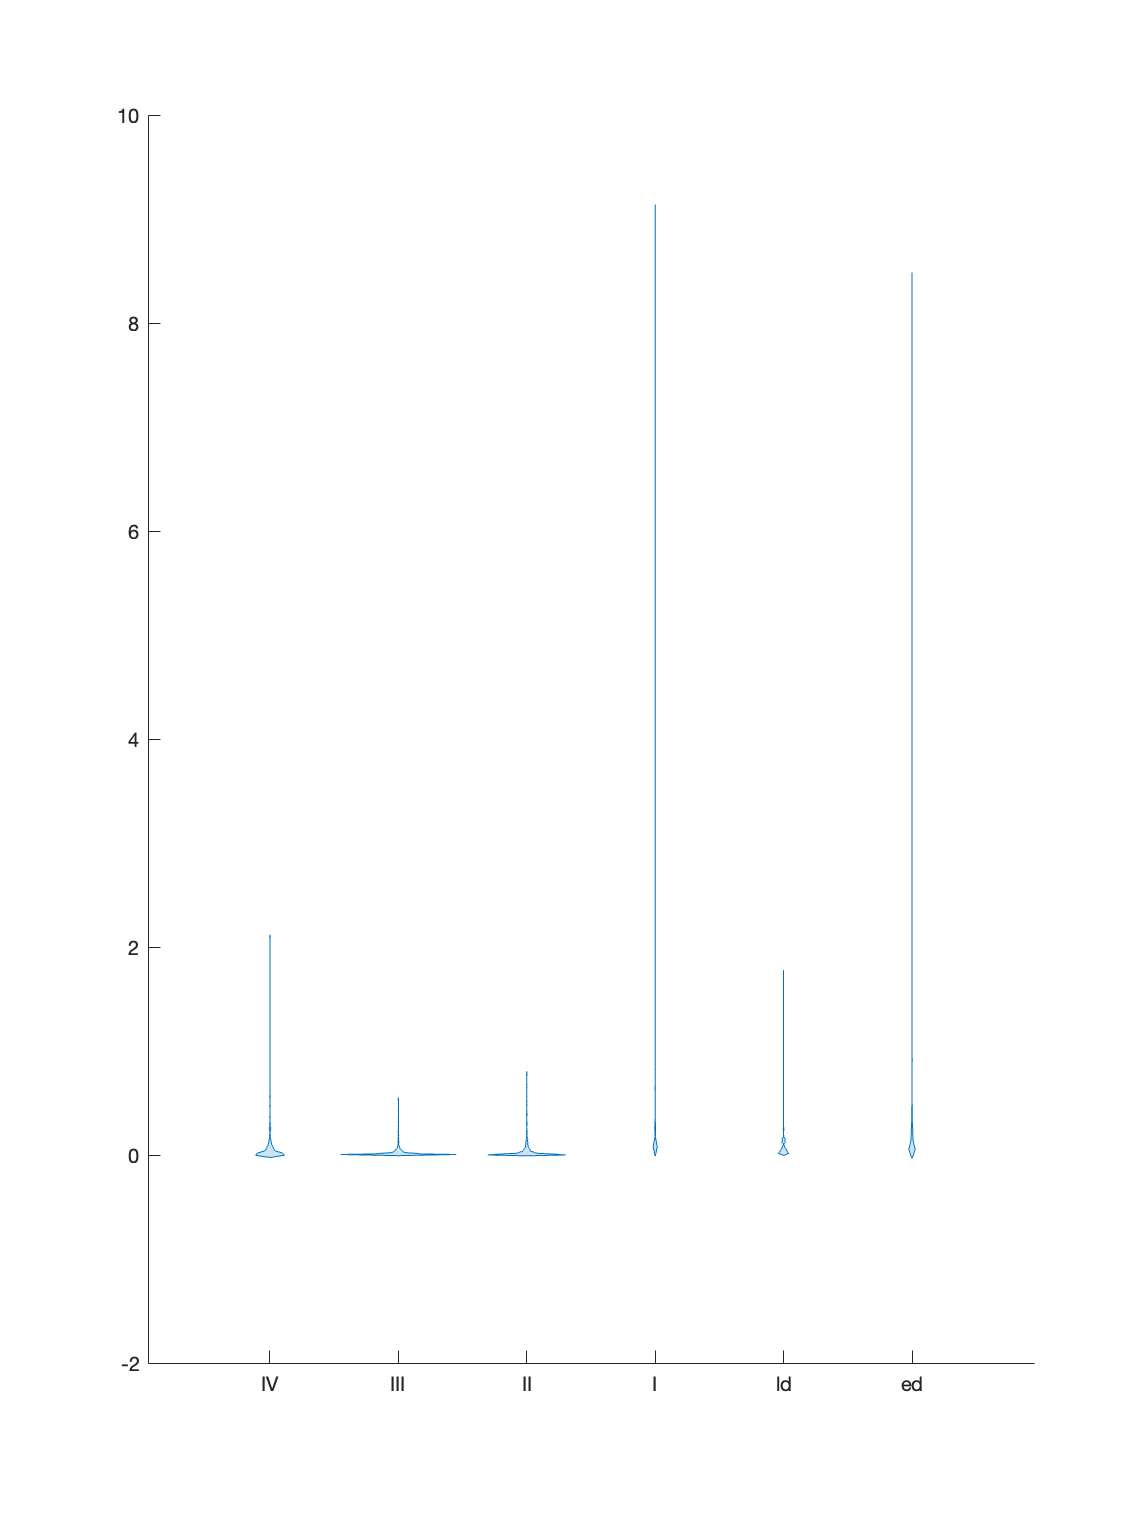

mmfig;
violinplot(g,y)

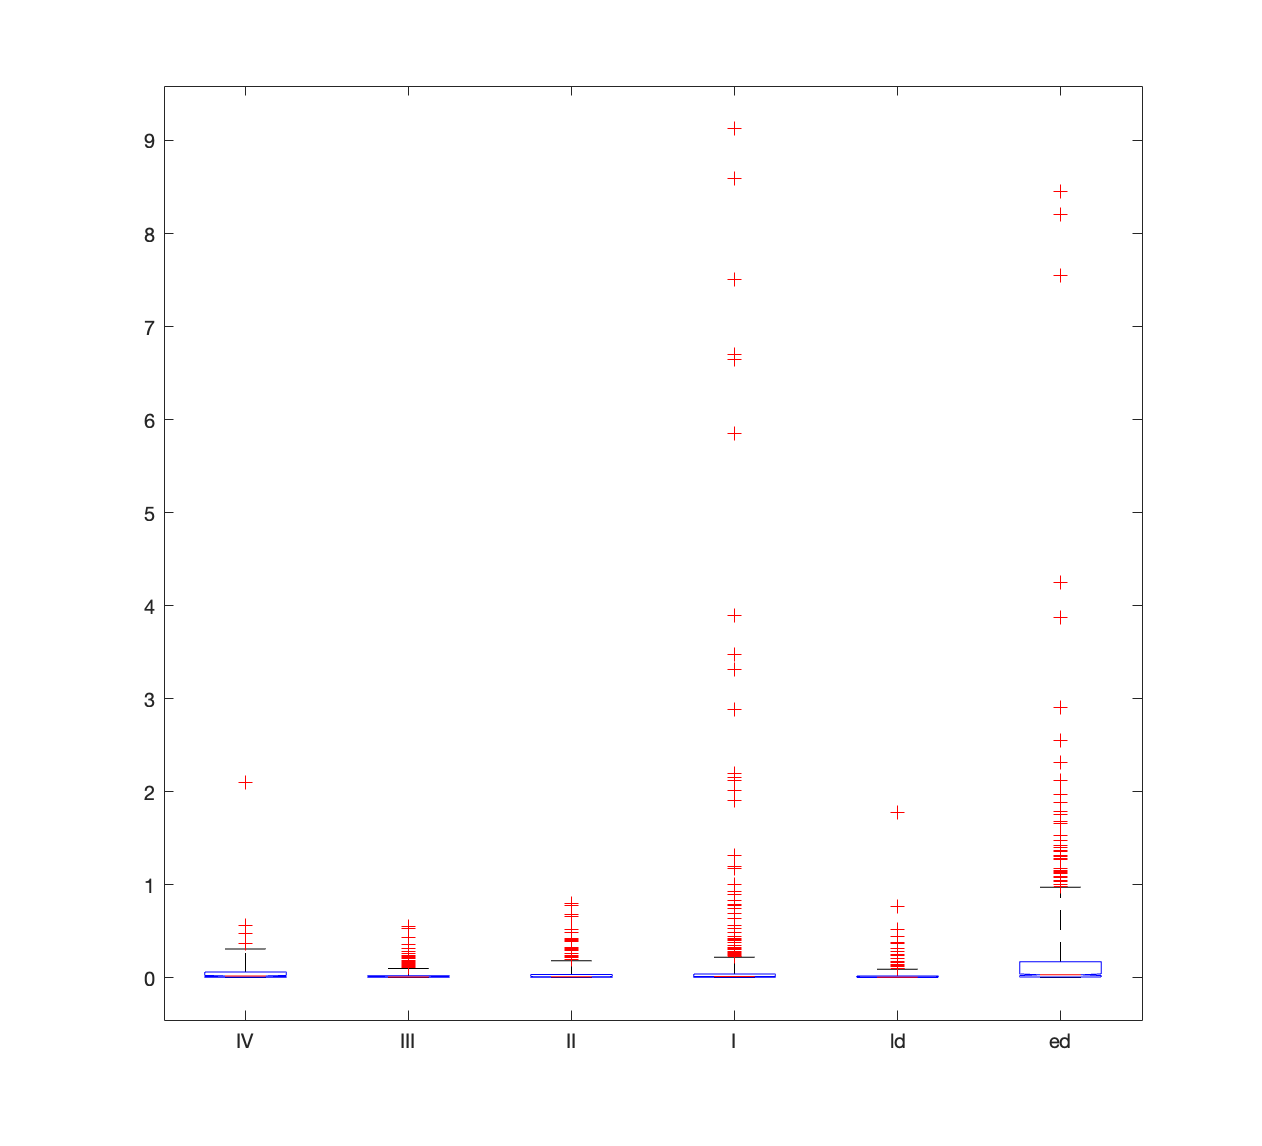

mmfig;
boxplot(y,g,"Whisker",5,Notch="on")

 A whisker length of 5 times the interquartile range was used to capture the exceptionally range of the early dying lysome volumes

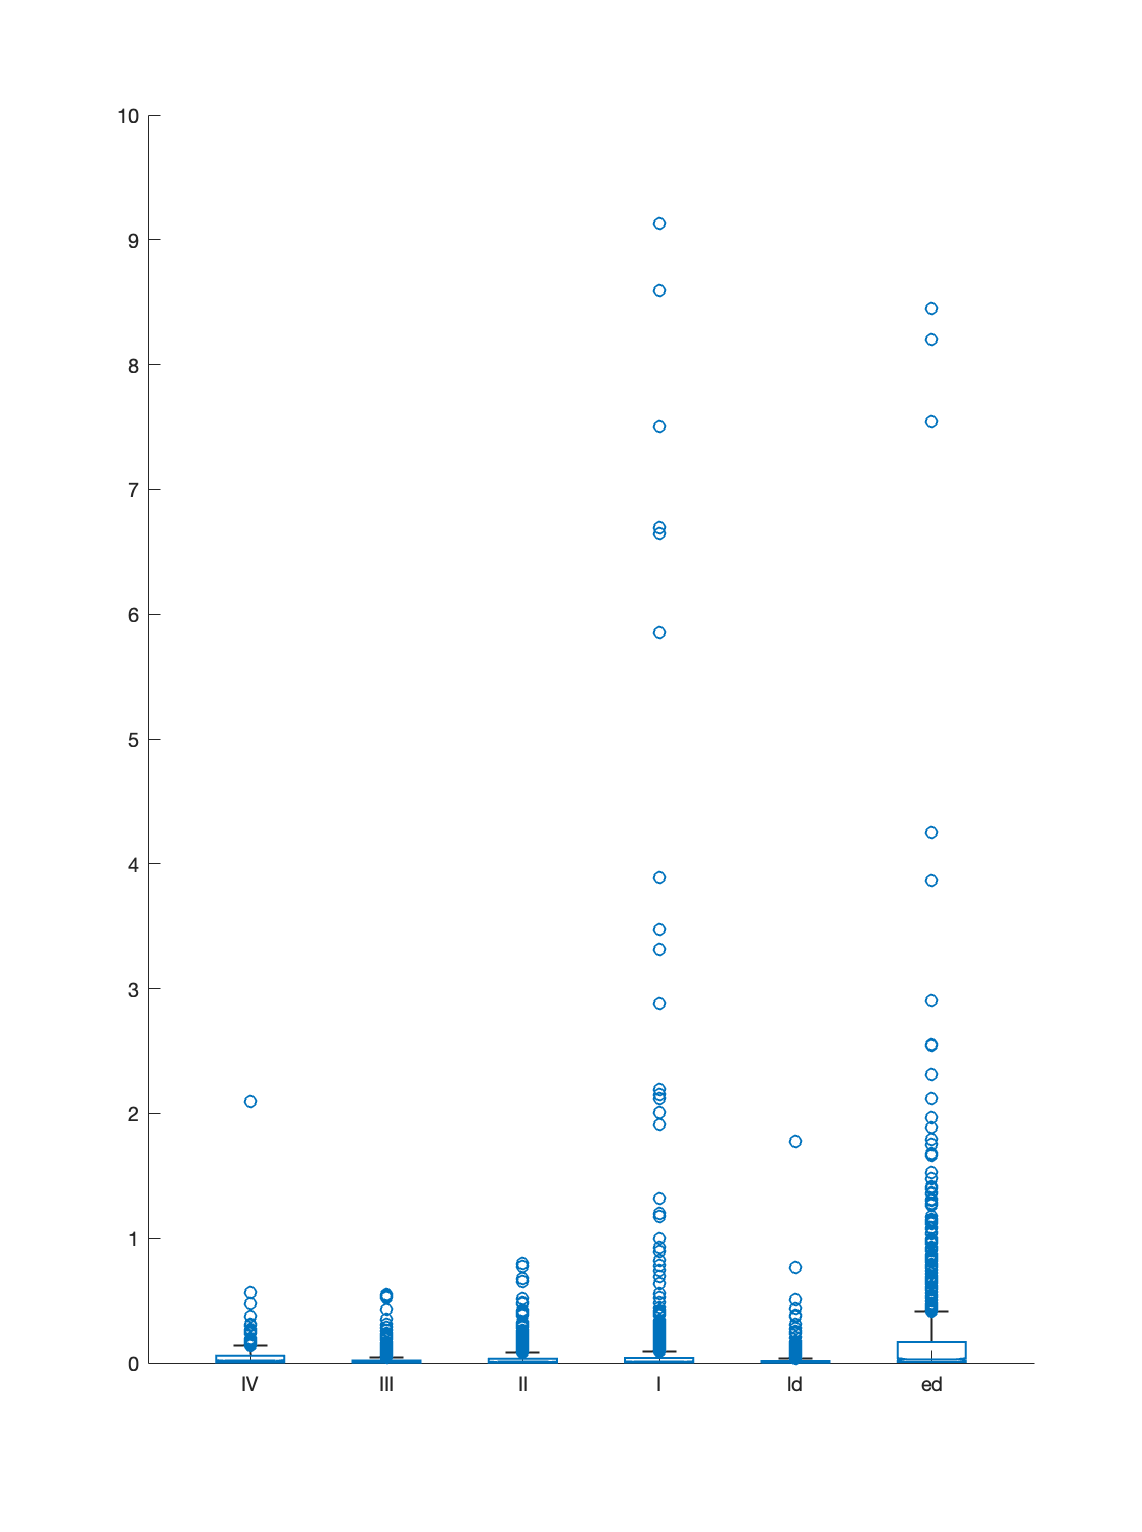

boxchart(g,y,'Notch','on')

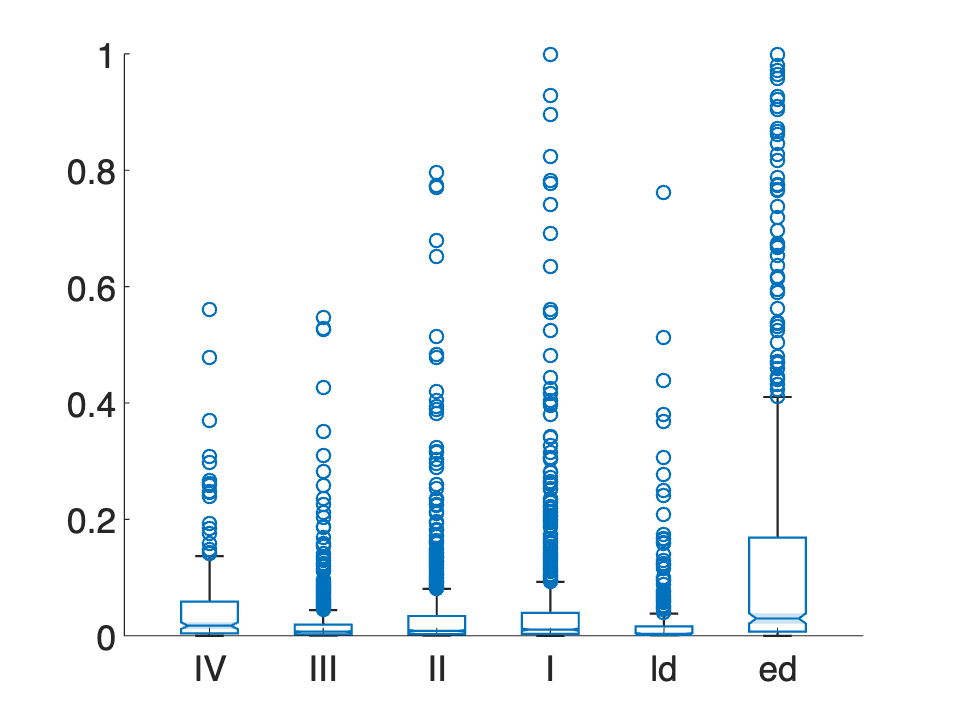

figure;
boxchart(g,y,'Notch','on')
ylim([0 1])

### Stats

Non-parametric anova

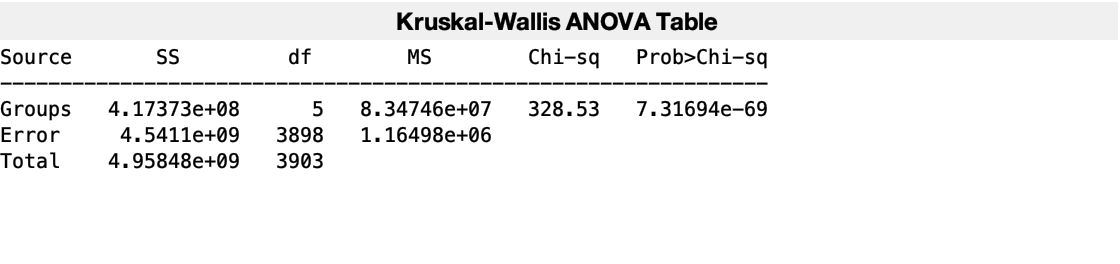

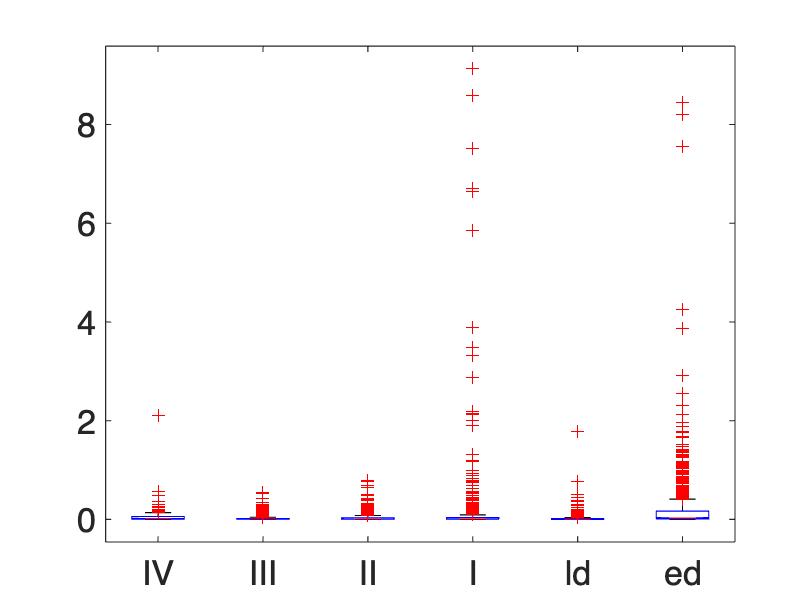

p =    7.3169e-69


tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df'  }    {'MS'        }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Groups'}    {[4.1737e+08]}    {[   5]}    {[8.3475e+07]}    {[  328.53]}    {[ 7.3169e-69]}
    {'Error' }    {[4.5411e+09]}    {[3898]}    {[ 1.165e+06]}    {0×0 double}    {0×0 double   }
    {'Total' }    {[4.9585e+09]}    {[3903]}    {0×0 double  }    {0×0 double}    {0×0 double   }


stats = struct with fields:
       gnames: {6×1 cell}
            n: [221 903 793 893 277 817]
       source: 'kruskalwallis'
    meanranks: [2157.6 1661.8 1858.3 1938 1427.4 2503.6]
         sumt: 0


[p,tbl,stats] = kruskalwallis(y,g)

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


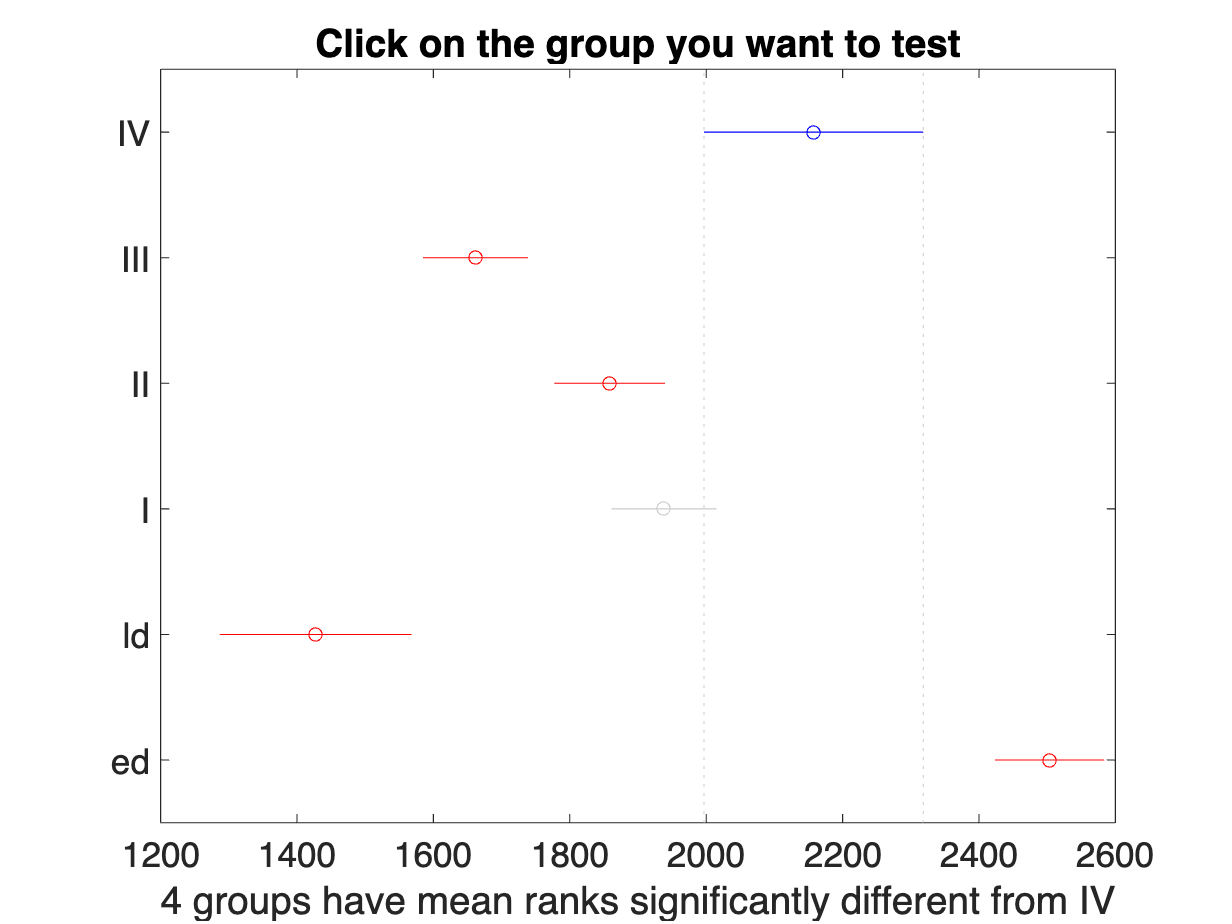

[c, ~,~, gnames] = multcompare(stats);

tbl = array2table(c,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"]);
tbl.("Group A")=gnames(tbl.("Group A"));
tbl.("Group B")=gnames(tbl.("Group B"))

tbl = 15×6 table
    Group A    Group B    Lower Limit      A-B      Upper Limit     P-value  
    _______    _______    ___________    _______    ___________    __________

    {'IV' }    {'III'}       254.69       495.75        736.8      6.7901e-08
    {'IV' }    {'II' }       54.995       299.32       543.64       0.0063959
    {'IV' }    {'I'  }      -21.703       219.62       460.94        0.098787
    {'IV' }    {'ld' }       440.52       730.22       1019.9      8.1901e-12
    {'IV' }    {'ed' }      -589.59      -346.06      -102.52      0.00072996
    {'III'}    {'II' }      -352.75      -196.43      -40.114       0.0046159
    {'III'}    {'I'  }      -427.72      -276.13      -124.54      3.1047e-06
    {'III'}    {'ld' }       13.863       234.48       455.09        0.02958

### Anova

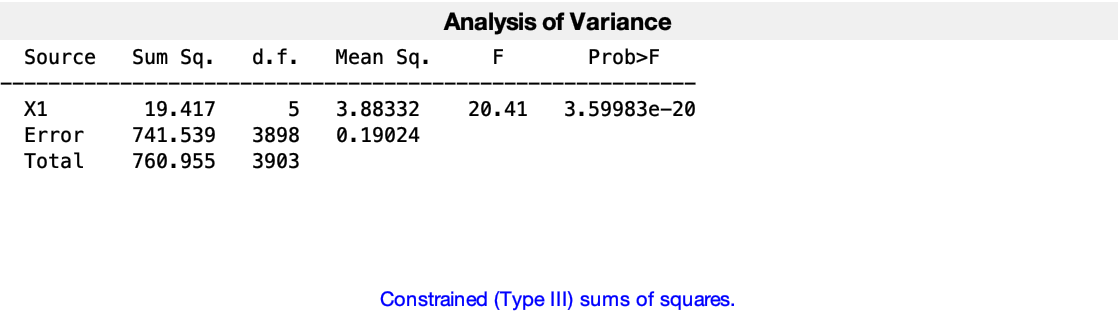

p =    3.5998e-20


tbl = 4×7 cell array
    {'Source'}    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'    }
    {'X1'    }    {[ 19.417]}    {[   5]}    {[        0]}    {[  3.8833]}    {[  20.413]}    {[3.5998e-20]}
    {'Error' }    {[ 741.54]}    {[3898]}    {[        0]}    {[ 0.19024]}    {0×0 double}    {0×0 double  }
    {'Total' }    {[ 760.96]}    {[3903]}    {[        0]}    {0×0 double}    {0×0 double}    {0×0 double  }


stats = struct with fields:
         source: 'anovan'
          resid: [3904×1 double]
         coeffs: [7×1 double]
            Rtr: [6×6 double]
       rowbasis: [6×7 double]
            dfe: 3898
            mse: 0.19024
    nullproject: [7×6 double]
          terms: 1
        nlevels: 6
     continuous: 0
         vmeans: 0
       termcols: [2×1 double]
     coeffnames: {7×1 cell}
           vars: [7×1 double]
       varnames: {'X1'}
       grpnames: {[6×1 cell]}
        vnested: []
            ems: [2×2 double]
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


[p,tbl,stats] = anovan(y,{g})

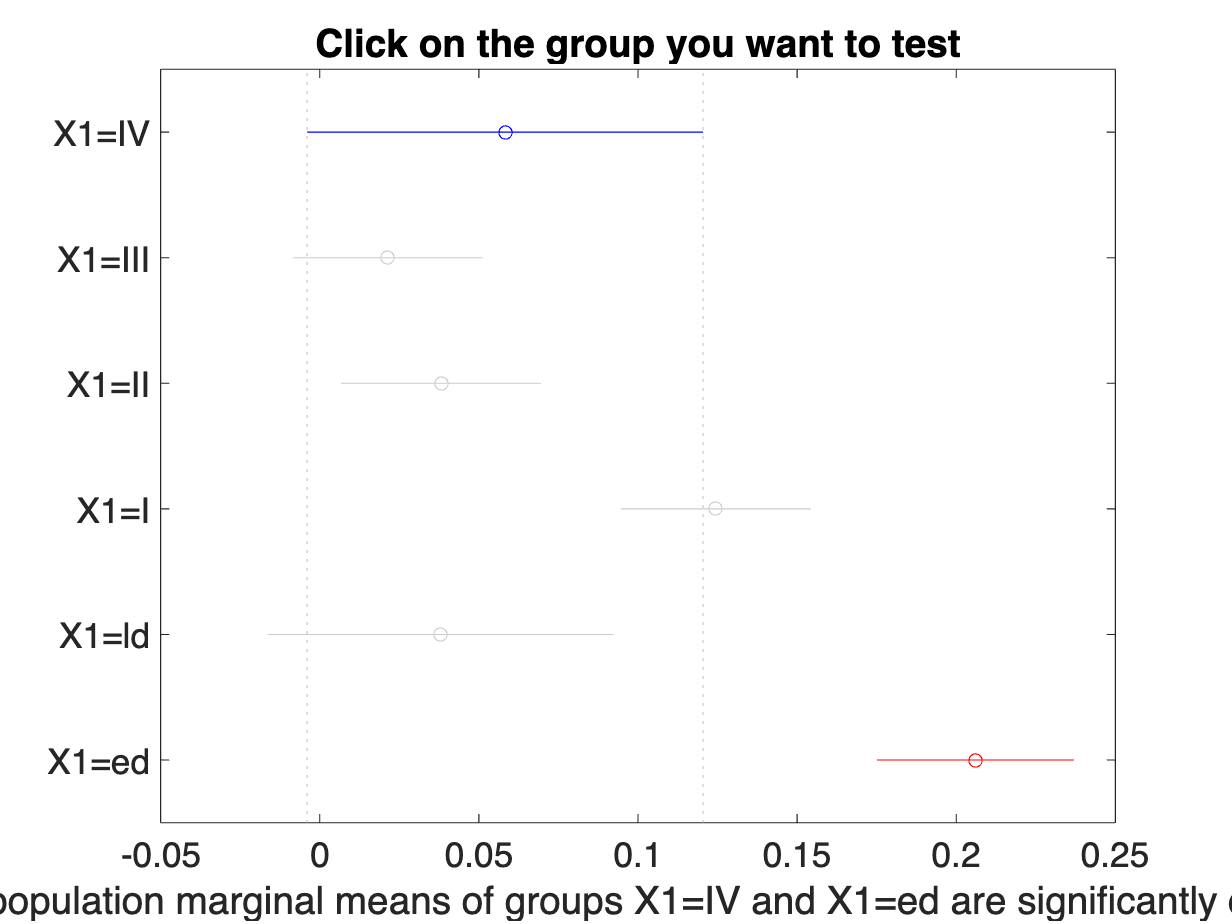

mcresults =             1            2    -0.056374     0.036906      0.13019      0.87013
            1            3    -0.074421     0.020122      0.11467      0.99061
            1            4     -0.15956    -0.066181     0.027202      0.33099
            1            5    -0.091794     0.020311      0.13242      0.99556
            1            6       -0.242     -0.14775    -0.053514   0.00011519
            2            3    -0.077273    -0.016783     0.043706      0.96919
            2            4     -0.16174     -0.10309    -0.044428   8.1448e-06
            2            5     -0.10196    -0.016595     0.068774      0.99383
            2            6     -0.24468     -0.18466     -0.12465   6.3631e-18
            3            4     -0.14695    -0.086303    -0.025656   0.00071206


gnames = 6×1 cell array
    {'X1=IV' }
    {'X1=III'}
    {'X1=II' }
    {'X1=I'  }
    {'X1=ld' }
    {'X1=ed' }


[mcresults,~,~,gnames] = multcompare(stats)

tbl = array2table(mcresults,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"]);
tbl.("Group A")=gnames(tbl.("Group A"));
tbl.("Group B")=gnames(tbl.("Group B"))

tbl = 15×6 table
     Group A       Group B      Lower Limit       A-B        Upper Limit     P-value  
    __________    __________    ___________    __________    ___________    __________

    {'X1=IV' }    {'X1=III'}     -0.056374       0.036906       0.13019        0.87013
    {'X1=IV' }    {'X1=II' }     -0.074421       0.020122       0.11467        0.99061
    {'X1=IV' }    {'X1=I'  }      -0.15956      -0.066181      0.027202        0.33099
    {'X1=IV' }    {'X1=ld' }     -0.091794       0.020311       0.13242        0.99556
    {'X1=IV' }    {'X1=ed' }        -0.242       -0.14775     -0.053514     0.00011519
    {'X1=III'}    {'X1=II' }     -0.077273      -0.016783      0.043706        0.96919
    {'X1=III'}    {'X1=I'  }      -0.16174       -0.10309     -0.044428     8.1448

## Calculate Lysosome Metrics per cell

- **LysCount**: total number of lysosomes found in a cell

- **LysTotalVolume**: summed volume of all lysosomes found in a cell

- **LysMedianVol**: median volume of lysosomes found in a cell

- **LysTraceMedian**: The median cross-sectional area of a lysosome in a given cell

### Lysosome Count

We adjusted lysosome count by volume. Any lysosome with a volume less 1.0, we counted as 1. Any lysosome with a volume greater or equal to 1.0, we counted as a multiple of its rounded volume (e.g. a volume of 1.75 would mean 2 lysosomes). 

### Add percent volume

Percent volume is total lysosome volume divided by cell volume


$$\textrm{LysCellRatio}=\frac{\textrm{Total}\;\textrm{Lysosome}\;\textrm{Volume}\;}{\textrm{Cell}\;\textrm{Volume}}$$


cellT = addLysMetrics2cellT(lysT,cellT)

cellT = 34×15 table
               Cell                Type    Health     Volume    SurfaceArea      SAV                   Filename                 PlotSort    LysCount    LysCountAdj    LysTotalVol    LysMedianVol    LysMeanVol    LysStdVol    LysCellRatio
    ___________________________    ____    _______    ______    ___________    _______    __________________________________    ________    ________    ___________    ___________    ____________    __________    _________    ____________

% Merge Dying Categories to simplify plotting
cellT.Health = mergecats(cellT.Health,{'early','late'},'dying');

Default figure color set to white.
Default font size set to 16.0.

cellT.PlotSort = mergecats(cellT.PlotSort,{'ed','ld'},'d');

## Visualization

mmSetFigPublication

### Plot: Lysosome Count and Median Lysosome Volume

merge categories here

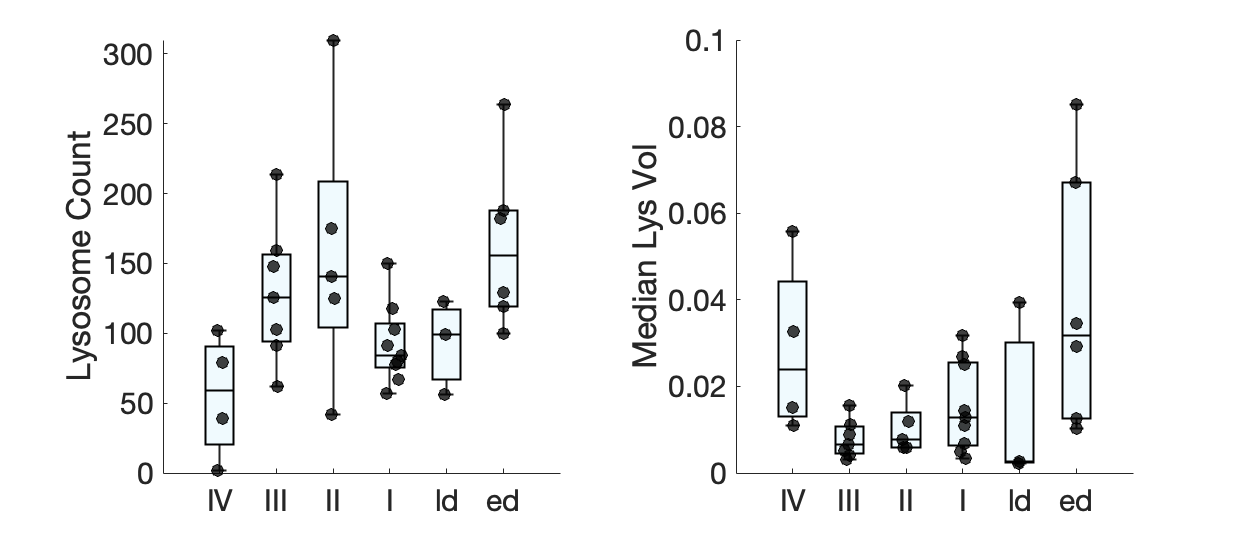

figure(Visible="on",Position=[1017 556 626 267],Color='white')

tiledlayout("horizontal")

% la = true(height(cellT),1);
% la = ~contains(cellT.Object,'AP37');
g = cellT.PlotSort;
y = cellT.LysCountAdj;

y2 = cellT.LysMedianVol;
y2_label = ("Median Lys Vol");

% hb = boxchart(g,y,GroupByColor=g) % makes the box charts too skinny

nexttile
hold on
boxchart(g,y,BoxFaceColor="#b3e4fa",BoxEdgeColor='k')
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.75, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.5)


ylabel("Lysosome Count")
xlabel("")
% grid on


nexttile
hold on

boxchart(g,y2,"BoxFaceColor","#b3e4fa",BoxEdgeColor='k')

swarmchart(g,y2, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.75, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)

% xlabel("cell type")
% grid off


ylabel(y2_label)

### Lysosome Count Differences

Are the number of lysosome per cell significantly different? Unlikely different

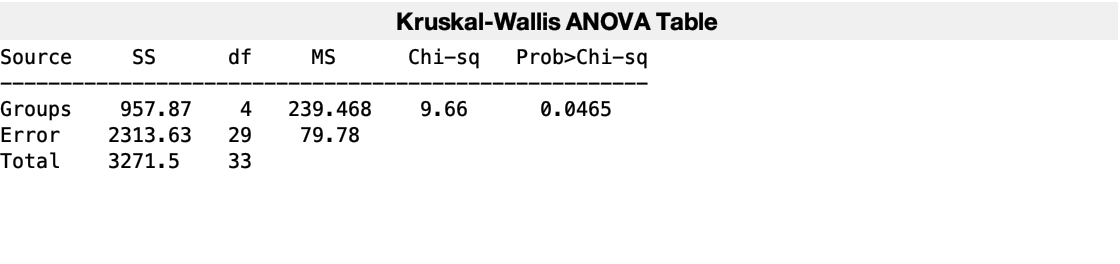

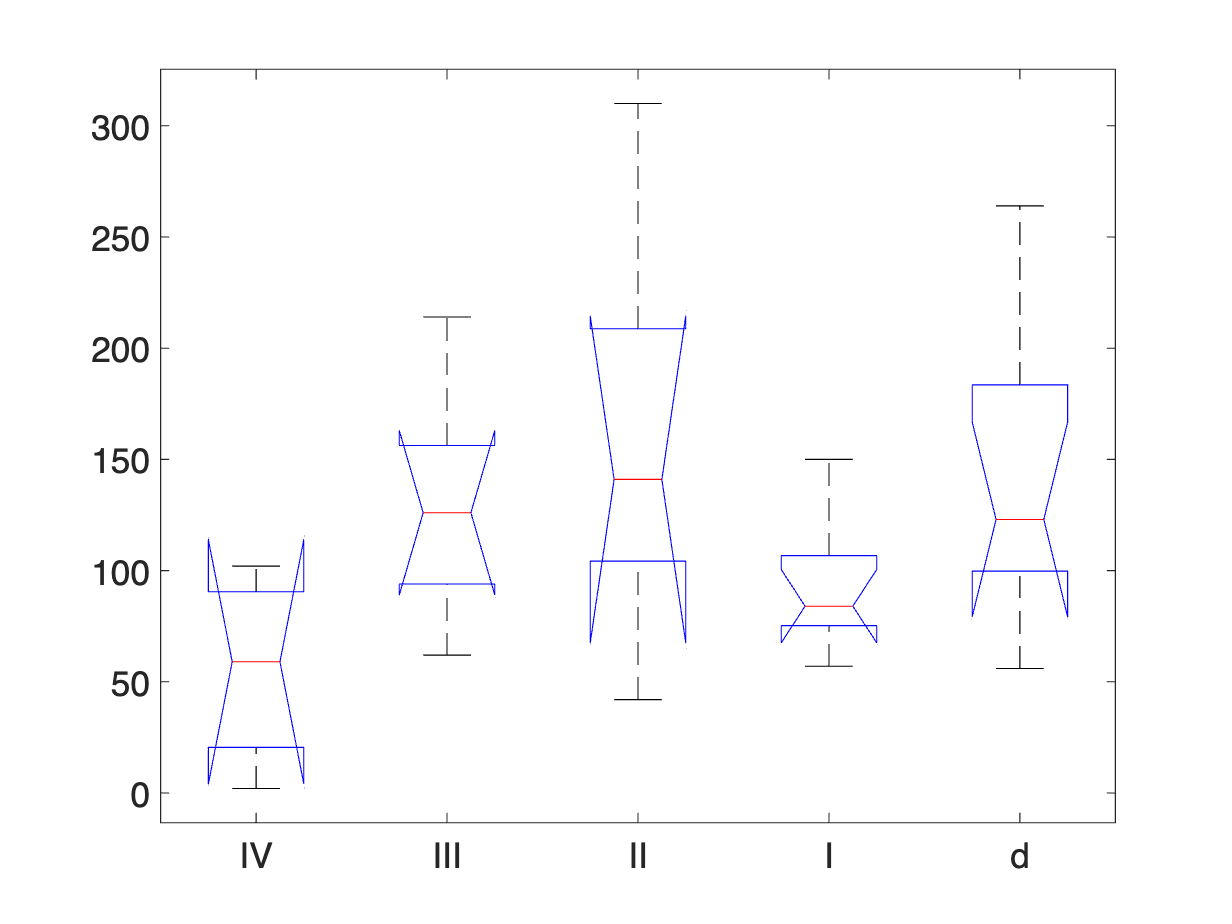

p =       0.04652


tbl = 4×6 cell array
    {'Source'}    {'SS'    }    {'df'}    {'MS'      }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Groups'}    {[957.87]}    {[ 4]}    {[  239.47]}    {[  9.6622]}    {[    0.04652]}
    {'Error' }    {[2313.6]}    {[29]}    {[   79.78]}    {0×0 double}    {0×0 double   }
    {'Total' }    {[3271.5]}    {[33]}    {0×0 double}    {0×0 double}    {0×0 double   }


stats = struct with fields:
       gnames: {5×1 cell}
            n: [4 7 5 9 9]
       source: 'kruskalwallis'
    meanranks: [7 20.714 22.6 13 21.333]
         sumt: 12


y = cellT.LysCountAdj;
g = cellT.PlotSort;
[p,tbl,stats] = kruskalwallis(y,g)

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


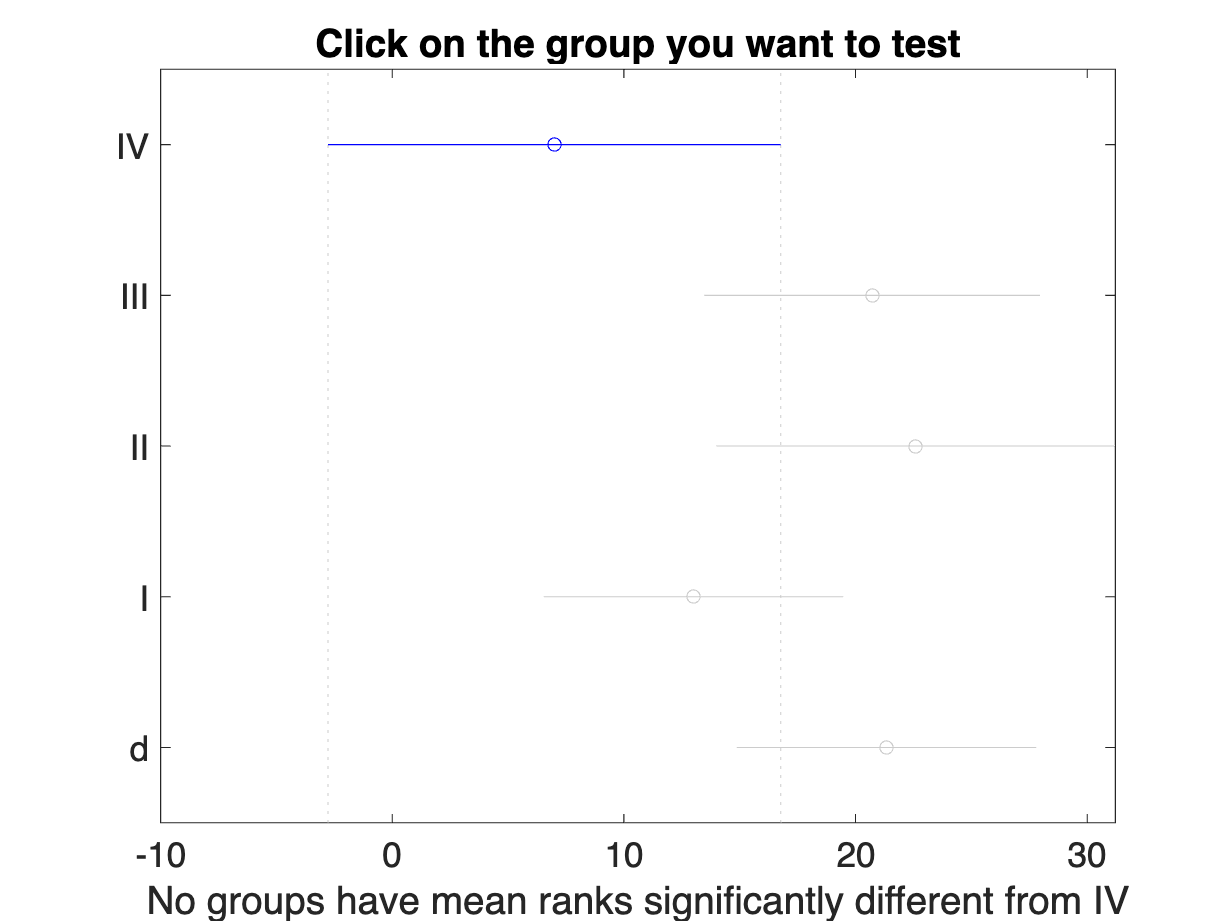

c =             1            2      -30.738      -13.714        3.309      0.18052
            1            3      -33.819        -15.6       2.6193      0.13366
            1            4      -22.321           -6       10.321       0.8542
            1            5      -30.654      -14.333       1.9876      0.11643
            2            3      -17.789      -1.8857       14.017      0.99764
            2            4      -5.9729       7.7143       21.401      0.53799
            2            5      -14.306     -0.61905       13.068      0.99995
            3            4       -5.549          9.6       24.749      0.41623
            3            5      -13.882       1.2667       16.416       0.9994
            4            5      -21.137      -8.3333       4.4699      0.38796


c= multcompare(stats)

## Focus on Type II Cells

### Get summary statistics

groupsummary(lysT(lysT.Type=="II",:),"Health",["mean" "median"],"Volume")

ans = 2×4 table
    Health     GroupCount    mean_Volume    median_Volume
    _______    __________    ___________    _____________

    early         817          0.20601         0.029769  
    healthy       793         0.038132        0.0083321  


### Generate Swarmcharts

#### Get data

lysT.Dying = mergecats(lysT.Health,{'early','late'},'dying');
lysT.Dying = reordercats(lysT.Dying,{'healthy','dying'});

la = lysT.Type == "II" & lysT.Dying == "healthy";
xh = lysT.Dying(la); 
yh = lysT.Volume(la); % healthy lysosome volumes

la = lysT.Type == "II" & lysT.Dying == "dying";
xd = lysT.Dying(la);
yd = lysT.Volume(la); % dying lysosome volumes

#### separate large clusters based on volume 

cutoff = 0.4;

yh2 = split_large_lys(yh);
yd2 = split_large_lys(yd);
xd2 = repmat(categorical("dying"),height(yd2),1);


function yd2 = split_large_lys(yd)

yd_low = yd(yd<=0.4);
yd_high = yd(yd>0.4);
yd_h_count = floor(yd_high./0.4); % number of 0.4 volumes in high vols
yd_u = repelem(repmat(0.4,height(yd_h_count),1),yd_h_count);
yd_h_frac = mod((yd_high./0.4), 1)*0.4; % left over volume
yd2 = [yd_low; yd_u; yd_h_frac];
end

ranksum(yh2, yd2)

ans =    2.2802e-77


#### Display Lysosome Volumes

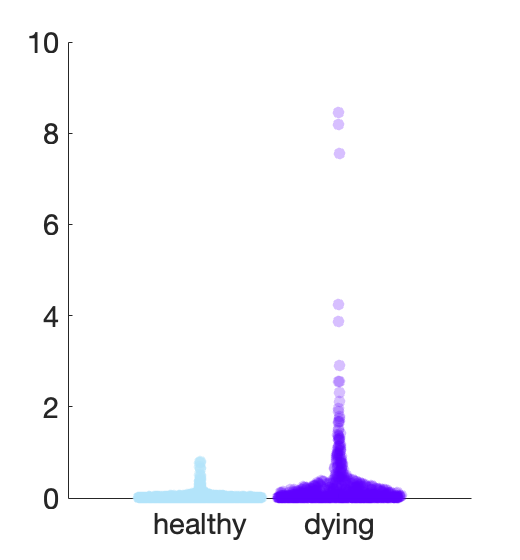

figure(Visible="on",Position=[1376 523 260 280], Color='white');
hold on

swarmchart(xh,yh,"filled",MarkerFaceAlpha=0.5)
swarmchart(xd,yd,"filled",MarkerFaceAlpha=0.25) 

colororder([validatecolor("#b3e4fa"); 0.3696	0	1.0000; ]) % Other blue #0072BD

#### Zoom in on Y-Axis

figure(Visible="on",Position=[1233 76 260 280], Color='white');

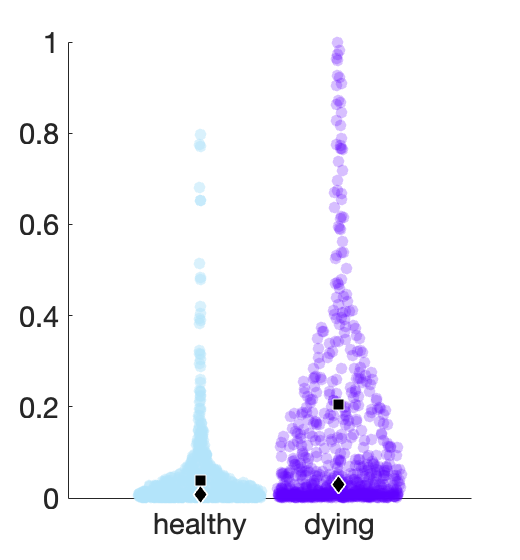

clf
hold on

cutOff = 1.0;

swarmchart(xh,yh,"filled",MarkerFaceAlpha=0.5)
ylim([0 cutOff]); % set Y Limit to 1

swarmchart(xd,yd,"filled",MarkerFaceAlpha=0.25) 
ylim([0 cutOff]);

colororder([validatecolor("#b3e4fa"); 0.3696	0	1.0000; ])

scatter(categorical("healthy"),median(yh),50,'kd','filled',MarkerEdgeColor='w',LineWidth=1)
scatter(categorical("healthy"),mean(yh),50,'ksq','filled',MarkerEdgeColor='w')

scatter(categorical("dying"),median(yd),50,'kd','filled',MarkerEdgeColor='w',LineWidth=1)
scatter(categorical("dying"),mean(yd),50,'ksq','filled',MarkerEdgeColor='w')

#### mann-whitney

[p,h, stats] = ranksum(yh,yd) % compare healthy lysosome volumes to dying lysosome volumes

p =    7.1069e-33


h = logical
   1


stats = struct with fields:
       zval: -11.942
    ranksum: 527383


s = sprintf('Lysosomes in dying Type II cells were significantly larger than the lysosomes in the healthy Type II cells, ');
s = sprintf('%smedian=%1.3f vs %1.3f, respectively,',s,  median(yd), median(yh));
s = sprintf('%s U(Ndying=%d, Nhealthy=%d)=%1.2f,z=%1.2f, p=%0.3e.',...
    s,...
    numel(yd),...
    numel(yh),...
    stats.ranksum,...
    stats.zval, ...
    p);
disp(s)

Lysosomes in dying Type II cells were significantly larger than the lysosomes in healthy Type II cells, median=0.028 vs 0.008, respectively, U(Ntreated=795, Nuntreated=793)=530562.00,z=-10.89, p=1.323e-27.


clipboard("copy",s) % copy to clipboard

#### Swarmchart using Table syntax

- can't get different colors when you use the table input syntax

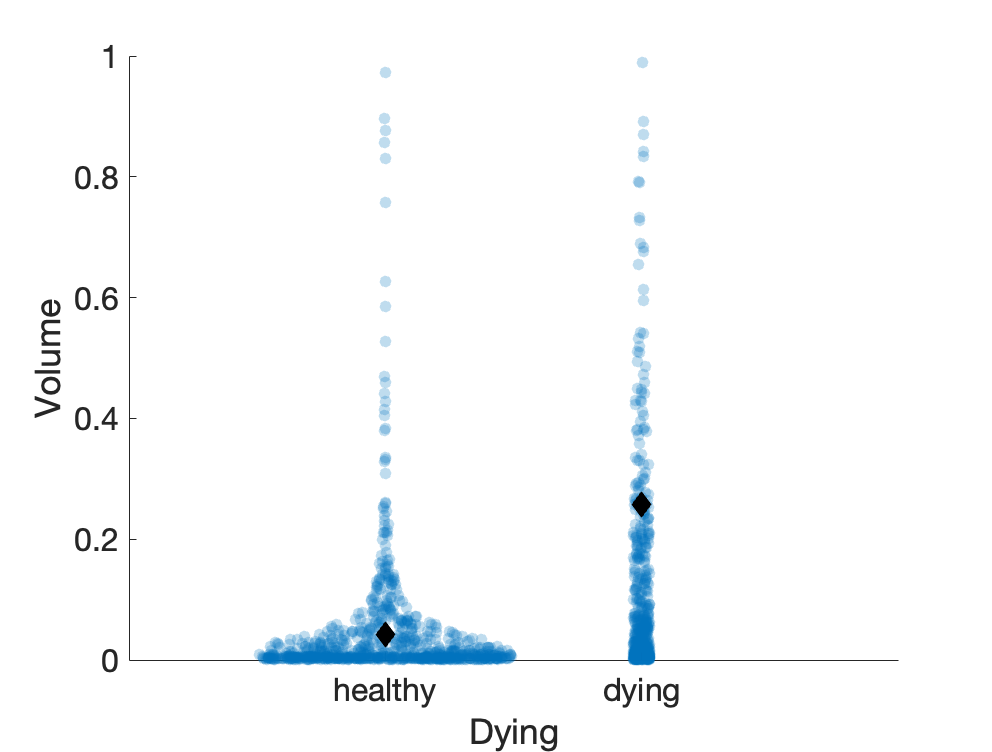

mmfig;

swarmchart(lysT(lysT.Type=="II",:),"Dying","Volume", ...
    "filled", ...
    MarkerFaceAlpha= 0.25,...
    XJitterWidth=1);
ylim([0 1]);

hold on
scatter(categorical("healthy"),0.042133,100,'kd','filled')
scatter(categorical("dying"),0.25679,100,'kd','filled')

## Cell Lysosome Volume Analysis

### Cell stats

cell_stats = groupsummary(cellT,"PlotSort",["min" "max"],"Volume")

cell_stats = 5×4 table
    PlotSort    GroupCount    min_Volume    max_Volume
    ________    __________    __________    __________

      IV            4           191.43         742.6  
      III           7           524.77        810.45  
      II            5           810.96        1173.7  
      I             9           394.35          1634  
      d             9            403.6        1984.4  


disp(cell_stats)

    PlotSort    GroupCount    min_Volume    max_Volume
    ________    __________    __________    __________

      IV            4           191.43         742.6  
      III           7           524.77        810.45  
      II            5           810.96        1173.7  
      I             9           394.35          1634  
      d             9            403.6        1984.4  



## Visualize

### Total Lysosome Volume per Cell

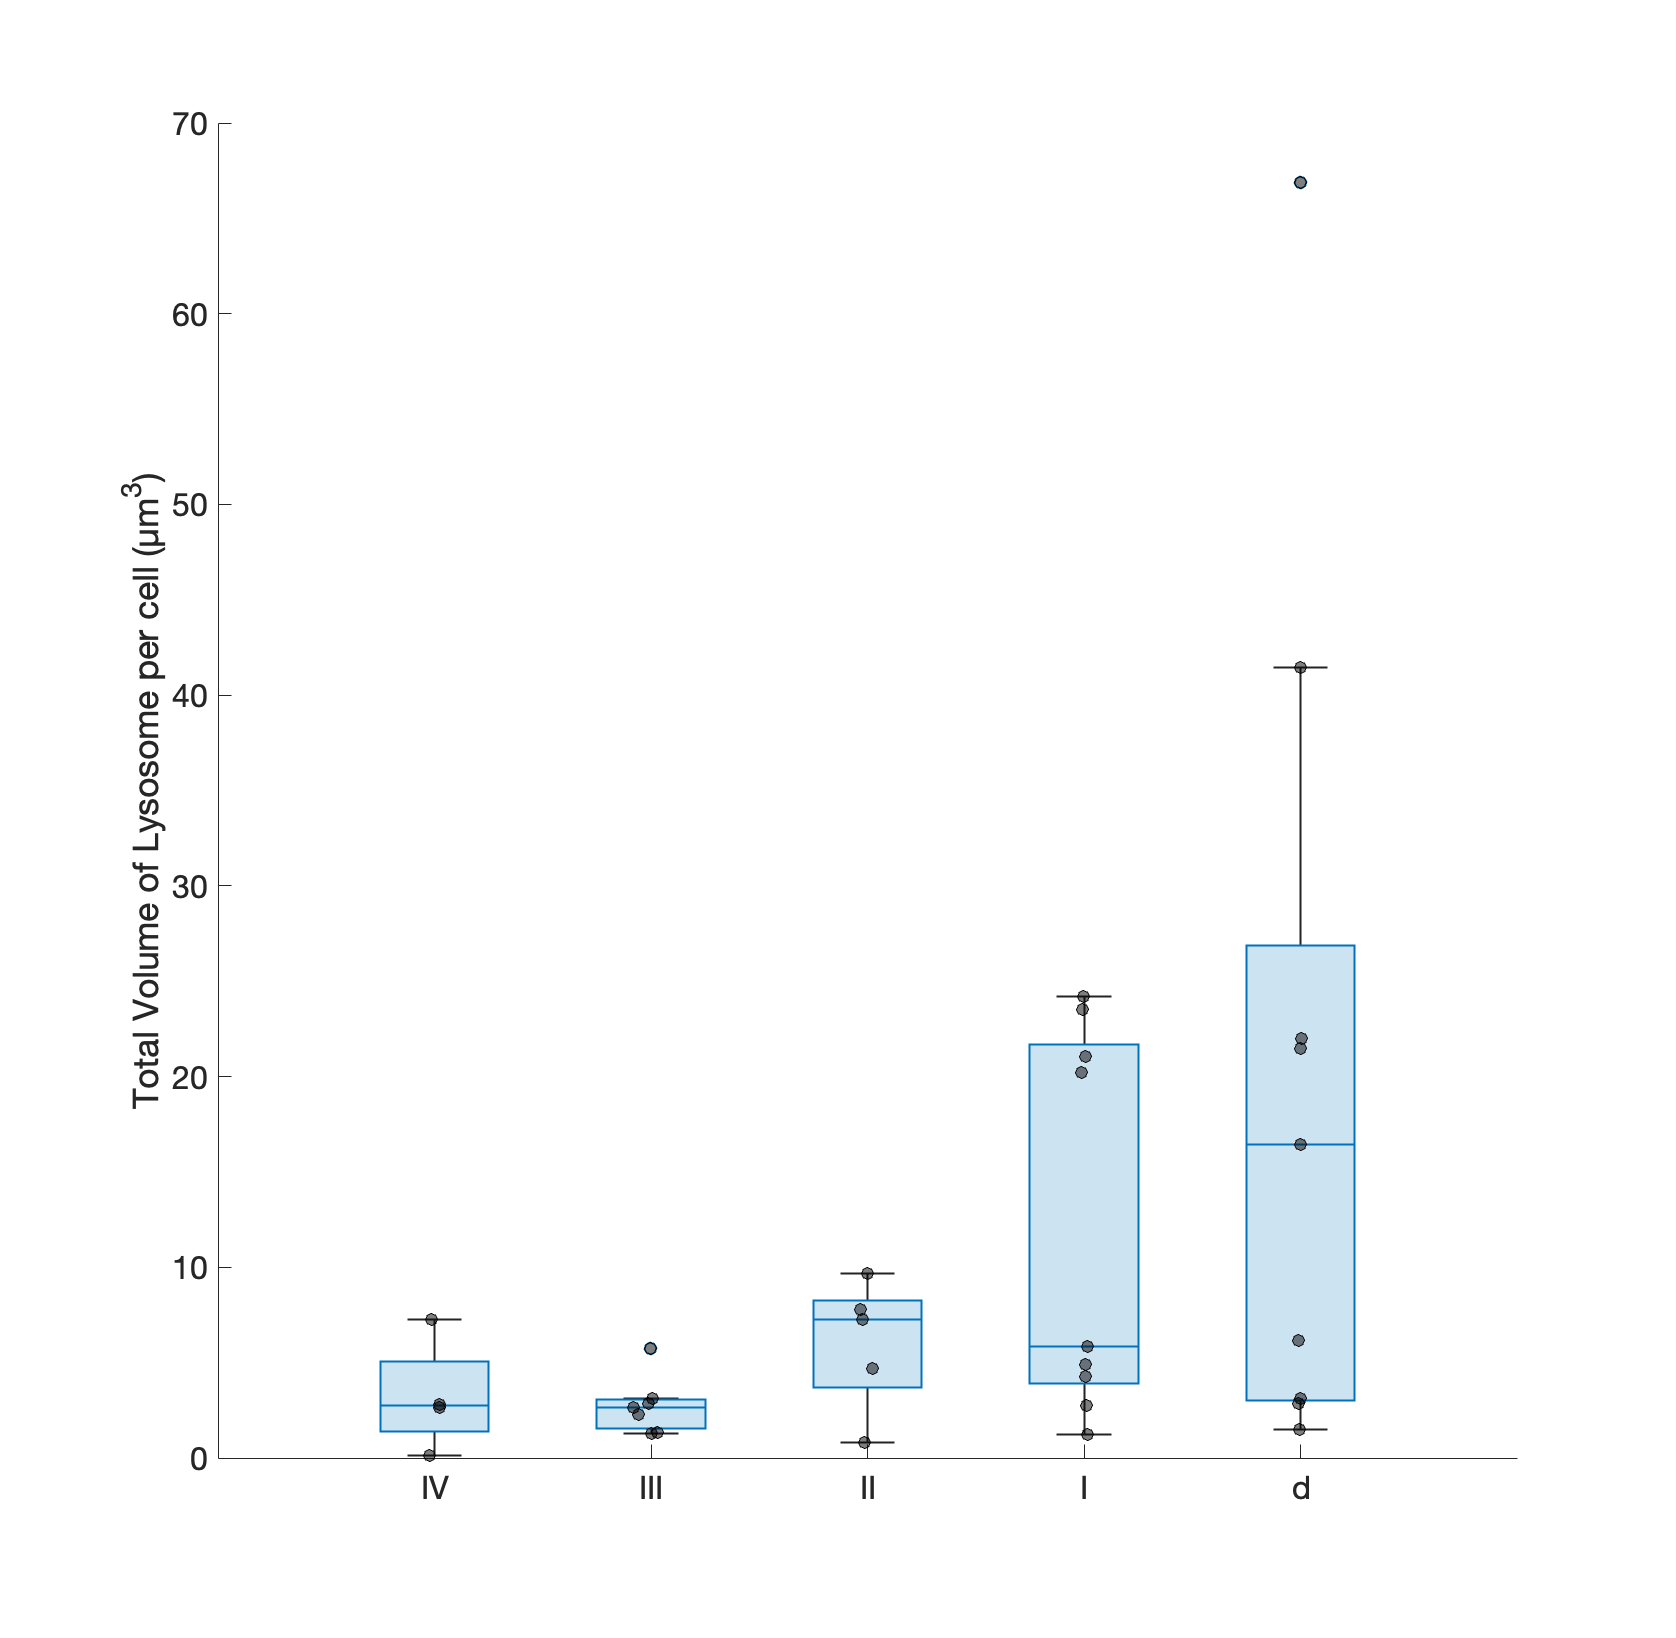

mmfig;

tiledlayout("horizontal")

g = cellT.PlotSort;
y = cellT.LysTotalVol;

hold on
boxchart(g,y,BoxFaceColor="#0072BD",Notch="off")
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
ylabel("Total Volume of Lysosome per cell (µm^3)")

### Ratio: Lysosome Total Volume to Cell Volume

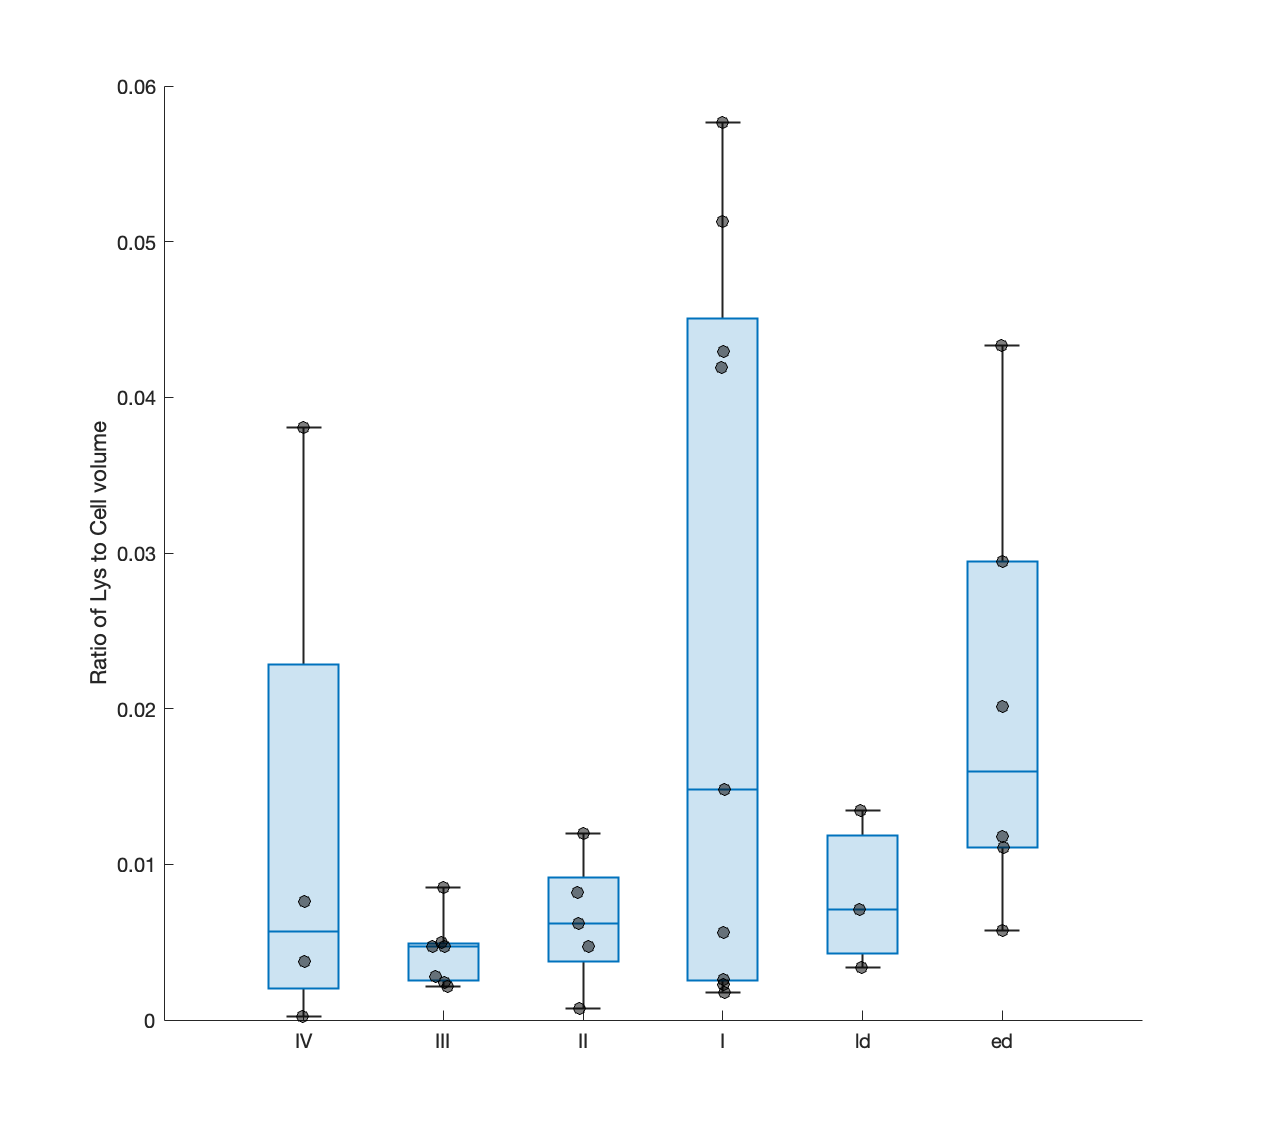

mmfig;
tiledlayout("horizontal")

g = cellT.PlotSort;
y = cellT.LysCellRatio;

hold on
boxchart(g,y,BoxFaceColor="#0072BD",Notch="off")
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
ylabel("Ratio of Lys to Cell volume")

# Local Functions

## Calculate lysT metrics per cell

- I and III healthy cells are about the same size

- I dying cell is larger than the other two cells

function cellT = addLysMetrics2cellT(lysT,cellT)

%summarize lysT data by cell 
s = groupsummary(lysT,"Cell",["sum","median","mean","std"],"Volume");
s.Properties.VariableNames = {'Cell',...
    'LysCount', 'LysTotalVol','LysMedianVol','LysMeanVol','LysStdVol'};

%adjust group count by volume
vol_cutoff = 1.0; 
t1 = lysT(lysT.Volume<vol_cutoff,:);
g1 = groupsummary(t1,"Cell");

t2 = lysT(lysT.Volume>=vol_cutoff,:); 
g2 = groupsummary(t2,"Cell","sum","Volume"); % use volume as a proxy for count

la = ismember(g1.Cell,g2.Cell);
g1.GroupCount(la) = g1.GroupCount(la)+round(g2.sum_Volume);

% merge tables and adjust column names
s = outerjoin(s,g1,"Keys","Cell","MergeKeys",true);
s.Properties.VariableNames = replace(s.Properties.VariableNames,'GroupCount','LysCountAdj');
s = movevars(s,"LysCountAdj","After","LysCount");

%manage cell names for cells that have apical "bits"
s.Cell = replace(s.Cell,"TB2_TCdying-01_cw","TB2_TCdying01"); % reconstruction includes the "bits" parts
s.Cell = replace(s.Cell,"TB2_TCdying-02_cw","TB2_TCdying02");
s.Cell = replace(s.Cell,"TB3_TC01_dying_cw","TB3_TC01");

% Add fields to cellT
cellT = join(cellT,s);
% cellT = sortrows(cellT,"Object");
cellT.LysCellRatio = cellT.LysTotalVol./ cellT.Volume;

end